mAdult=[];

## define parameters

number of size groups:

n = 10;
% number of generlist groups:
k = 2;
% run in parallel?:
bParallel = false;
% endtime of simulation
tEnd=720;
% timestep:
d=0.1;
% set HTL parameters:
mortHTL=0.1;
mHTL=1/500^1.5;
bQuadraticHTL=false;
bDecliningHTL=false;

## setup simulation

p = setupGeneralistsSimpleK(n,k, bParallel);

done loading input parameters


p = parametersChemostat(p);
p.tEnd = tEnd;
p.d = d;

% Change colors for groups of Generalists:
r=[13 15 56 119 189];
g=[139 178 192 207 227];
b=[217 242 242 242 242];
j=linspace(0.3,0.9,k);

blue(1,:)=[58/255,67/255,186/255];
blue(2,:)=[4/255,146/255,194/255];
blue(3,:)=[130/255,237/255,253/255];

for i=2:k+1
    %p.colGroup{i}=[0,0,j(i-1)];
    p.colGroup{i}=blue(i-1,:);
end
%Change color of N so I can see generalists

p.colNutrients{1}=[0,1,1];

%p.umin=p.umin.*0.5;
%p.u0(p.idxB:p.n) = 0.5;
%
% Set to "normal" HTL mortality if there are no copepods:
%

setHTL(mortHTL, mHTL, bQuadraticHTL,bDecliningHTL);

## Simulate

iterate over d=0.001 to 0.1

dvector=logspace(-3,-1,20);
for i=1:length(dvector)
    p.d=dvector(i);
    sim = simulateChemostat(p, 100);
    B(i,:)=sim.B(end,:);
end

## Plot

standard plots: plotSimulation_trine(sim);

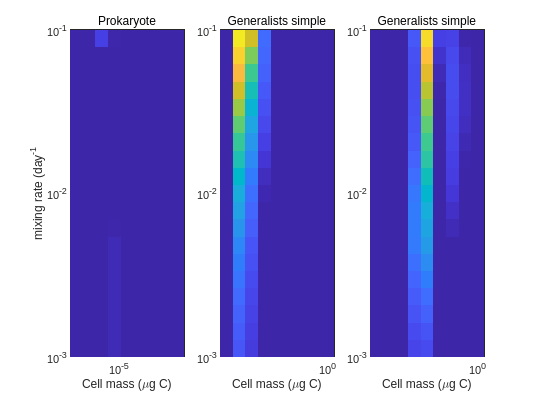

figure('color','w');
for i=1:p.nGroups
subplot(1,p.nGroups,i)
m=p.m(3:end);
[x,y]=meshgrid(p.m(p.ixStart(i):p.ixEnd(i)),dvector);
pcolor(x,y,B(:,p.ixStart(i)-2:p.ixEnd(i)-2));
shading flat
set(gca,'XScale','log','YScale','log')
xlabel('Cell mass (\mug C)')
if i==1
    ylabel('mixing rate (day^{-1}')
end
subtitle(p.nameGroup{i})
end